# 5. Improving Network Performance

#   5.1. Data Preprocessing

## Load Dataset

xData - Each row of the array stores a 32 x 32 color image. The first 1024 entries contain the red channel values, the next 1024 the green, the final 1024 the blue.

yLabel - a list of 10000 numbers in the range of 0-9.

xData - 배열의 각 행은 32 x 32 컬러 이미지를 저장합니다. 처음 1024개 항목에는 빨간색 채널 값이 포함되고, 다음 1024개 항목에는 녹색, 마지막 1024개 항목에는 파란색이 포함됩니다.

yLabel - 0-9 범위의 10000개 숫자 목록입니다.

load("data_batch_1.mat")
data

data = 10000×3072 uint8 행렬
    59    43    50    68    98   119   139   145   149   149   131   125   142   144   137   129   137   134   124   139   139   133   136   139   152   163   168   159   158   158   152   148    16     0    18    51    88   120   128   127   126   116   106   101   105   113   109   112   119   109
   154   126   105   102   125   155   172   180   142   111   106   109   123   127   181   217   209   166   164   158   116   102    95    90    72    60    56    77    94    91    87    79   140   145   125   124   150   152   174   178   134   110   133   163   192   218   240   245   241   238
   255   253   253   253   253   253   253   253   253   253   253   253   253   253   253   254   245   226   244   241   250   253   252   250   253   253   253   253   253   253   253   253   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   238   208
    28    37    38    42    44    40    40    24    32    43    30    

labels

labels = 10000×1 uint8 열 벡터
   6
   9
   9
   4
   1
   1
   2
   7
   8
   3


## 1. Preprocessing xData (permute(transpose) -> reshape -> permute(imrotate))

xData is a 10000 x 3072 array, which contains 10000 observations and  32 x 32 x 3 sized images. Your goal is to reshape xData to 32 x 32 x 3 x 10000.

xData는 10000 x 3072 배열로, 10000개의 관측값과 32 x 32 x 3 크기의 이미지를 포함합니다. 목표는 xData의 모양을 32 x 32 x 3 x 10000으로 바꾸는 것입니다.

### 1. Reshape xData to 3072 x 10000

There are two ways to create 3072 x 10000, by using `permute` or `transpose`.

순열 또는 전치를 사용하여 3072 x 10000을 만드는 두 가지 방법이 있습니다.

    a. By `permute`

`ex) data = 3 X 5 X 10 >> permute(data, [3,2,1]) >> 10 X 5 X 3. []안에는 각 요소의 순서`

dataPermute1 = permute(data, [2,1])

dataPermute1 = 3072×10000 uint8 행렬
    59   154   255    28   170   159   164    28   134   125    53   142   164    17   100   100   235   110   197    23   153   252    86   126    73   162   131    45   128   202   126   236    50     7   172   251   169    95   110    98   101   145   127    99   139    54    94    77   191   255
    43   126   253    37   168   150   105    30   131   110    54   172   162    17    98   100   235   142   198    47   174   249    96   102    71   164   124    42   121   202   122   233    51     7   171   247   131    88   223   119    94   145   148    98   144    59    72    76   190   255
    50   105   253    38   177   153   118    33   128   102    56   176   162    17    99   101   237   151   201    52   155   250   115   117    77   169   116    35   138   204   126   234    42     5   168   247   193    86   243   109    98   148   192   100   146    56    60    78   190   255
    68   102   253    42   183   154   129    62   133   106  

    b. By `transpose`

dataTransposed = data'

dataTransposed = 3072×10000 uint8 행렬
    59   154   255    28   170   159   164    28   134   125    53   142   164    17   100   100   235   110   197    23   153   252    86   126    73   162   131    45   128   202   126   236    50     7   172   251   169    95   110    98   101   145   127    99   139    54    94    77   191   255
    43   126   253    37   168   150   105    30   131   110    54   172   162    17    98   100   235   142   198    47   174   249    96   102    71   164   124    42   121   202   122   233    51     7   171   247   131    88   223   119    94   145   148    98   144    59    72    76   190   255
    50   105   253    38   177   153   118    33   128   102    56   176   162    17    99   101   237   151   201    52   155   250   115   117    77   169   116    35   138   204   126   234    42     5   168   247   193    86   243   109    98   148   192   100   146    56    60    78   190   255
    68   102   253    42   183   154   129    62   133   106

# Reshape Vector into Matrix

A = [1:10;11:2:30]

A =      1     2     3     4     5     6     7     8     9    10
    11    13    15    17    19    21    23    25    27    29


B = reshape(A,[5,4]) %열을 기준으로 reshape

B =      1    15     6    25
    11     4    21     9
     2    17     7    27
    13     5    23    10
     3    19     8    29


reshape(A,5,[]) %아무것도 입력 안해주면 5행으로만 자동 구성, 열도 가능

ans =      1    15     6    25
    11     4    21     9
     2    17     7    27
    13     5    23    10
     3    19     8    29


The size of `dataPermute1` variable is 3072 x 1000.

### 2. Reshape it to 32 x 32 x 3 x 10000 using `reshape` and view the 10000th image of `dataReshape` variable

dataReshape = reshape(dataPermute1, [32,32,3,10000])

dataReshape = 32×32×3×10000 uint8 배열
dataReshape(:,:,1,1) =

    59    16    25    33    50    71    97   115   137   154   154   145   142   158   145   148   149   147   152   145   143   143   141   143   149   172   202   216   220   208   180   177
    43     0    16    38    59    84   111   119   128   154   155   146   141   154   149   146   143   134   117   127   127   125   131   139   133   144   187   193   201   201   173   168
    50    18    49    87   102   110   123   130   132   156   156   146   140   142   147   145   144   140   114   128   129   131   139   138   136   135   151   168   186   198   186   179
    68    51    83   106   127   129   130   140   128   140   147   135   144   143   147   147   151   148   123   133   129   128   139   149   147   136   128   151   172   191   194   188
    98    88   110   115   124   136   136   133   119   123   133   127   147   132   136   133   132   135   126   132   130   123   138   160   150   135   122   13

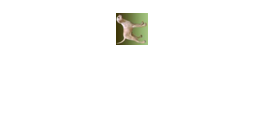

imshow(dataReshape(:,:,:,10000))

You recognize the image is a dog but it is rotated.

### 3. Rotate the images

    a. By `permute`

dataPermute2 = permute(dataReshape, [2,1,3,4])

dataPermute2 = 32×32×3×10000 uint8 배열
dataPermute2(:,:,1,1) =

    59    43    50    68    98   119   139   145   149   149   131   125   142   144   137   129   137   134   124   139   139   133   136   139   152   163   168   159   158   158   152   148
    16     0    18    51    88   120   128   127   126   116   106   101   105   113   109   112   119   109   105   125   127   122   131   124   121   131   132   133   133   123   119   122
    25    16    49    83   110   129   130   121   113   112   112   106   105   128   124   130   127   122   115   120   130   131   139   127   126   127   130   142   130   118   120   109
    33    38    87   106   115   117   114   105   107   121   125   109   113   146   133   127   118   117   127   122   132   137   136   131   124   130   132   135   130   125   121    94
    50    59   102   127   124   121   120   114   107   125   129   106   108   124   121   108    98   110   117   120   134   140   131   141   135   127   121   

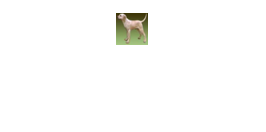

imshow(dataPermute2(:,:,:,10000))

    b. By `imrotate(Not recommended)`

dataRotate = imrotate(dataReshape, 270)

dataRotate = 32×32×3×10000 uint8 배열
dataRotate(:,:,1,1) =

   148   152   158   158   159   168   163   152   139   136   133   139   139   124   134   137   129   137   144   142   125   131   149   149   145   139   119    98    68    50    43    59
   122   119   123   133   133   132   131   121   124   131   122   127   125   105   109   119   112   109   113   105   101   106   116   126   127   128   120    88    51    18     0    16
   109   120   118   130   142   130   127   126   127   139   131   130   120   115   122   127   130   124   128   105   106   112   112   113   121   130   129   110    83    49    16    25
    94   121   125   130   135   132   130   124   131   136   137   132   122   127   117   118   127   133   146   113   109   125   121   107   105   114   117   115   106    87    38    33
    67    75    87   103   119   121   127   135   141   131   140   134   120   117   110    98   108   121   124   108   106   129   125   107   114   120   121   124 

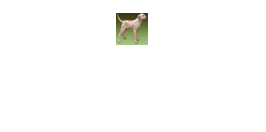

imshow(dataRotate(:,:,:,10000))

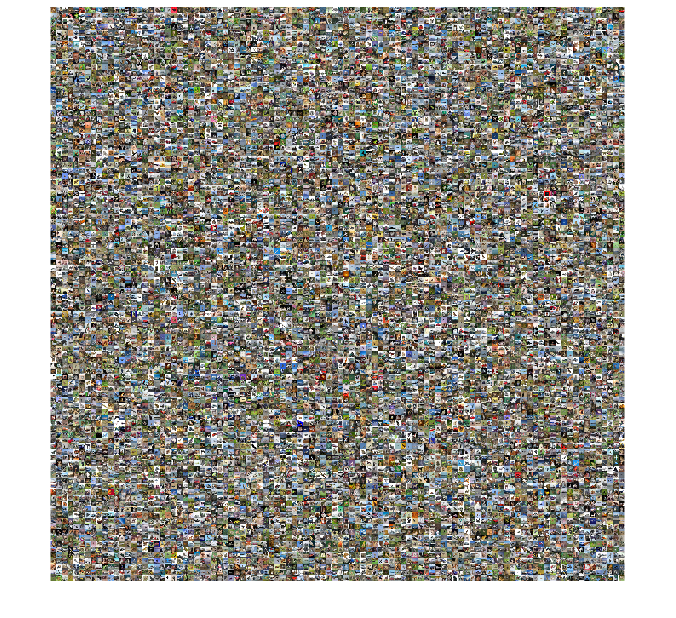

montage(dataPermute2)

xData = dataPermute2;

## 2. Preprocessing yLabel

`labels` variable is 10000 x 1 unit8 vector. Convert it to a categorical variable and display the type and number of categories.

yLabel = categorical(labels)

yLabel = 10000×1 categorical 배열
     6 
     9 
     9 
     4 
     1 
     1 
     2 
     7 
     8 
     3 
     4 
     7 
     7 
     2 
     9 
     9 
     9 
     3 
     2 
     6 
     4 
     3 
     6 
     6 
     2 
     6 
     3 
     5 
     4 
     0 


categories(yLabel) % the type of categories

ans = 10×1 cell 배열
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


summary(yLabel) % the number of categories

     0      1005 
     1       974 
     2      1032 
     3      1016 
     4       999 
     5       937 
     6      1030 
     7      1001 
     8      1025 
     9       981 


## 3. Spliting Dataset

Partition the data into train and test sets. As in Machine Learning, `cvpartition` is used for partition.

데이터를 학습 세트와 테스트 세트로 분할합니다. 기계 학습에서와 마찬가지로 cvpartition은 파티션에 사용됩니다.

% 1.
pt = cvpartition(yLabel, "HoldOut", 0.2) %HoldOut은 몇대몇을 가리킴. 즉 8대 2

pt = 홀드아웃 교차 검증 분할
   NumObservations: 10000
       NumTestSets: 1
         TrainSize: 8000
          TestSize: 2000

tridx = training(pt)

tridx = 10000×1 logical 배열
   1
   1
   1
   0
   0
   0
   1
   0
   1
   0


testidx = test(pt) % testidx = ~tridx

testidx = 10000×1 logical 배열
   0
   0
   0
   1
   1
   1
   0
   1
   0
   1



xTrain = xData(:,:,:,tridx);
yTrain = yLabel(tridx);

xTest = xData(:,:,:, ~tridx);
yTest = yLabel(~tridx);

summary(yTrain)

     0      804 
     1      779 
     2      826 
     3      813 
     4      799 
     5      750 
     6      824 
     7      801 
     8      820 
     9      784 


summary(yTest)

     0      201 
     1      195 
     2      206 
     3      203 
     4      200 
     5      187 
     6      206 
     7      200 
     8      205 
     9      197 


 % 2.
pt = cvpartition(yLabel, "HoldOut", 0.2) %HoldOut은 몇대몇을 가리킴. 즉 8대 2

pt = 홀드아웃 교차 검증 분할
   NumObservations: 10000
       NumTestSets: 1
         TrainSize: 8000
          TestSize: 2000


xTrain = xData(:,:,:,pt.training);
yTrain = yLabel(pt.training);

xTest = xData(:,:,:, pt.test);
yTest = yLabel(pt.test);

summary(yTrain)

     0      804 
     1      780 
     2      825 
     3      812 
     4      800 
     5      749 
     6      824 
     7      801 
     8      820 
     9      785 


summary(yTest)

     0      201 
     1      194 
     2      207 
     3      204 
     4      199 
     5      188 
     6      206 
     7      200 
     8      205 
     9      196 
